%% Dual Quaternion Basics Homework - Part 1
% File: dual_quaternion_basics_homework_part1.m

%% Homework example
% Clean up routine to remove variables from your workspace
clear all;
close all;

%% Initialize the DQ Robotics namespace
include_namespace_dq

%% Helper functions for dual quaternions
% Dual quaternion: dq = [qr; qd] where qr is rotation, qd is dual part

function q = quat_from_axis_angle(axis, theta)
    axis = axis / norm(axis);
    q = [cos(theta/2); sin(theta/2) * axis];
end

function q = quat_mul(q1, q2)
    w1 = q1(1); v1 = q1(2:4);
    w2 = q2(1); v2 = q2(2:4);
    w = w1*w2 - dot(v1, v2);
    v = w1*v2 + w2*v1 + cross(v1, v2);
    q = [w; v];
end

function qc = quat_conj(q)
    qc = [q(1); -q(2:4)];
end

function dq = dq_from_rt(qr, t)
    qt = [0; t(:)];
    qd = 0.5 * quat_mul(qt, qr);
    dq = [qr; qd];
end

function dq = dq_mul(dq1, dq2)
    qr1 = dq1(1:4); qd1 = dq1(5:8);
    qr2 = dq2(1:4); qd2 = dq2(5:8);
    qr = quat_mul(qr1, qr2);
    qd = quat_mul(qr1, qd2) + quat_mul(qd1, qr2);
    dq = [qr; qd];
end

function t = dq_get_translation(dq)
    qr = dq(1:4); qd = dq(5:8);
    temp = quat_mul(qd, quat_conj(qr));
    t = 2 * temp(2:4);
end

function R = quat_to_rotmat(q)
    w = q(1); x = q(2); y = q(3); z = q(4);
    R = [1-2*(y^2+z^2),   2*(x*y-z*w), 2*(x*z+y*w);
         2*(x*y+z*w), 1-2*(x^2+z^2),   2*(y*z-x*w);
         2*(x*z-y*w), 2*(y*z+x*w), 1-2*(x^2+y^2)];
end

function v_rot = rotate_vector_by_dq(dq, v)
    qr = dq(1:4);
    v_quat = [0; v(:)];
    result = quat_mul(quat_mul(qr, v_quat), quat_conj(qr));
    v_rot = result(2:4);
end

%% Solutions
%% Question 1
% Store in x_1 the pose transformation of translation of 1m in x-axis,
% followed by rotation of pi/3 rad about z-axis

t1 = [1; 0; 0];
theta1 = pi/3;
qr_z = quat_from_axis_angle([0;0;1], theta1);
dq_trans1 = dq_from_rt([1;0;0;0], t1);
dq_rot1 = dq_from_rt(qr_z, [0;0;0]);
x_1 = dq_mul(dq_rot1, dq_trans1);

fprintf('Question 1:\n');

Question 1:


fprintf('x_1 = [%.6f; %.6f; %.6f; %.6f; %.6f; %.6f; %.6f; %.6f]\n', x_1);

x_1 = [0.866025; 0.000000; 0.000000; 0.500000; 0.000000; 0.433013; 0.250000; 0.000000]



%% Question 2
% Store in x_2 the pose transformation of translation of -1m in z-axis,
% followed by rotation of pi/4 rad about x-axis

t2 = [0; 0; -1];
theta2 = pi/4;
qr_x = quat_from_axis_angle([1;0;0], theta2);
dq_trans2 = dq_from_rt([1;0;0;0], t2);
dq_rot2 = dq_from_rt(qr_x, [0;0;0]);
x_2 = dq_mul(dq_rot2, dq_trans2);

fprintf('\nQuestion 2:\n');


Question 2:


fprintf('x_2 = [%.6f; %.6f; %.6f; %.6f; %.6f; %.6f; %.6f; %.6f]\n', x_2);

x_2 = [0.923880; 0.382683; 0.000000; 0.000000; 0.000000; 0.000000; 0.191342; -0.461940]



%% Question 3
% Calculate sequential transformation by x_1, then x_2, then x_3
% Store in x_3 and plot

x_0_1 = x_1;
x_0_2 = dq_mul(x_2, x_0_1);
x_3 = x_0_2;

fprintf('\nQuestion 3:\n');


Question 3:


fprintf('x_3 = [%.6f; %.6f; %.6f; %.6f; %.6f; %.6f; %.6f; %.6f]\n', x_3);

x_3 = [0.800103; 0.331414; -0.191342; 0.461940; 0.065263; 0.495722; 0.396677; -0.304381]


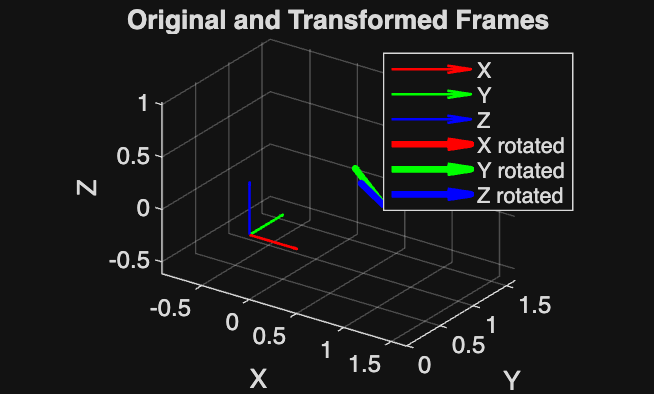


% Plot x_3
figure('Name', 'Frame x_3');
hold on; axis equal; grid on;

ex = [1;0;0]; ey = [0;1;0]; ez = [0;0;1];
quiver3(0,0,0, ex(1),ex(2),ex(3), 0.5, 'r', 'LineWidth', 1);
quiver3(0,0,0, ey(1),ey(2),ey(3), 0.5, 'g', 'LineWidth', 1);
quiver3(0,0,0, ez(1),ez(2),ez(3), 0.5, 'b', 'LineWidth', 1);

t3 = dq_get_translation(x_3);
ex_rot = rotate_vector_by_dq(x_3, ex);
ey_rot = rotate_vector_by_dq(x_3, ey);
ez_rot = rotate_vector_by_dq(x_3, ez);

quiver3(t3(1),t3(2),t3(3), ex_rot(1),ex_rot(2),ex_rot(3), 0.5, 'r', 'LineWidth', 2.5);
quiver3(t3(1),t3(2),t3(3), ey_rot(1),ey_rot(2),ey_rot(3), 0.5, 'g', 'LineWidth', 2.5);
quiver3(t3(1),t3(2),t3(3), ez_rot(1),ez_rot(2),ez_rot(3), 0.5, 'b', 'LineWidth', 2.5);

title('Original and Transformed Frames');
xlabel('X'); ylabel('Y'); zlabel('Z');
legend('X', 'Y', 'Z', 'X rotated', 'Y rotated', 'Z rotated');
view(35, 25);
hold off;


%% Question 4
% Obtain rotation of x_3 without using rotation()

qr_3 = x_3(1:4);
R_3 = quat_to_rotmat(qr_3);

fprintf('\nQuestion 4:\n');


Question 4:


fprintf('Rotation quaternion: [%.6f; %.6f; %.6f; %.6f]\n', qr_3);

Rotation quaternion: [0.800103; 0.331414; -0.191342; 0.461940]


fprintf('Rotation matrix:\n');

Rotation matrix:


disp(R_3);

    0.5000   -0.8660         0
    0.6124    0.3536   -0.7071
    0.6124    0.3536    0.7071




%% Question 5
% Obtain translation of x_3 without using translation()

t_3 = dq_get_translation(x_3);

fprintf('\nQuestion 5:\n');


Question 5:


fprintf('Translation: [%.6f; %.6f; %.6f]\n', t_3);

Translation: [0.500000; 1.319479; -0.094734]



%% Question 6
% Obtain pose transformation of rotation pi/3 about z-axis followed by
% translation 1m in x-axis, store in x_4
% Is it the same as x_1? If different, why?

dq_rot_first = dq_from_rt(qr_z, [0;0;0]);
dq_trans_after = dq_from_rt([1;0;0;0], [1;0;0]);
x_4 = dq_mul(dq_trans_after, dq_rot_first);

fprintf('\nQuestion 6:\n');


Question 6:


fprintf('x_4 = [%.6f; %.6f; %.6f; %.6f; %.6f; %.6f; %.6f; %.6f]\n', x_4);

x_4 = [0.866025; 0.000000; 0.000000; 0.500000; 0.000000; 0.433013; -0.250000; 0.000000]



diff = norm(x_4 - x_1);
fprintf('\nIs x_4 the same as x_1? ');


Is x_4 the same as x_1? 

if diff < 1e-10
    fprintf('YES\n');
else
    fprintf('NO (difference = %.6e)\n', diff);
    fprintf('Why different: Order matters - translation then rotation vs\n');
    fprintf('rotation then translation produce different results because\n');
    fprintf('rotation changes the direction of translation.\n');
end

NO (difference = 5.000000e-01)


Why different: Order matters - translation then rotation vs


rotation then translation produce different results because


rotation changes the direction of translation.



fprintf('\nHomework complete!\n');


Homework complete!
